# Boas Práticas

clear all;
close all;
clc;

N = 26; %numero de harmonicas

## Definindo o sinal g(t)

g = @(t) exp(-t);   %função do sinal
T0 = 1;             %periodo do sinal
w0 = 2*pi/T0;       %frequencia angular
f0 = 1/T0;          %frequencia fundamental
n = [-N:1:N];       %harmonicas de foular
f = n*f0;           %frequencia das harmonicas


## Calcular a integral de fourier

syms t n T0

Dn = inv(T0)*int(exp(-(1i*n*w0+1)*t),t,0,T0);
D0 = inv(T0)*int(exp(-t),t,0,T0);


## Calcular os valores numéricos

T0 = 1;         %redefine o periodo
n = [-N:1:N];   %redefine o valor de n
Dn = eval(Dn);  %valor numerico
D0 = eval(D0);  %valor medio
Dn(N+1) = D0;   %valor correto de Dn


## Sintese do sinal g(t)

M = 1000;           %Pontos de simulacao
Ts=T0/M;            %simulacao
tempo = [0:Ts:3*T0];  %vetor de tempo

soma = 0;

for k = 0:2*N

    soma = soma + Dn(k+1)*exp(1i*n(k+1)*w0*tempo);
   
end

gt = soma;


## Visualizacao de Dn e g(t)

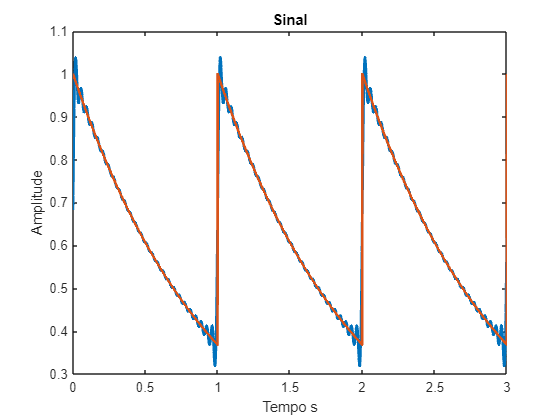


figure(1)

plot(tempo,real(gt),tempo,g(rem(tempo,1)),"LineWidth",2)
xlabel("Tempo s");
ylabel("Amplitude")
title("Sinal")